Analizando caso: SH_0


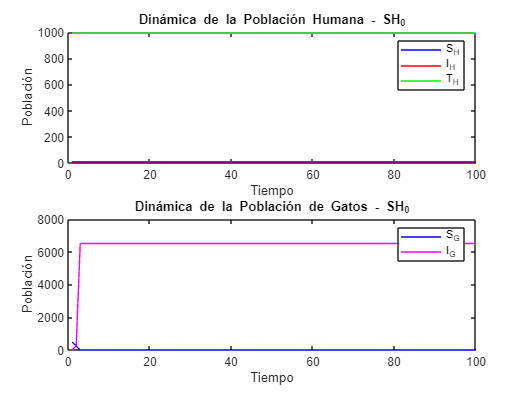

Resultados finales:
 S_H = 0.00
 I_H = 9.00
 T_H = 991.00
 I_G = 6502.00
 S_G = 0.00



Analizando caso: SG_0


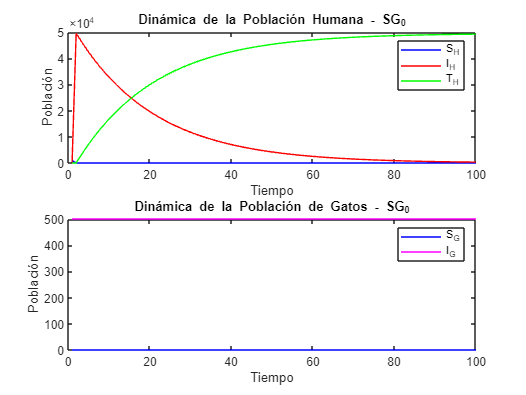

Resultados finales:
 S_H = 0.00
 I_H = 308.00
 T_H = 49203.00
 I_G = 500.00
 S_G = 0.00



Analizando caso: IG_GT_SH


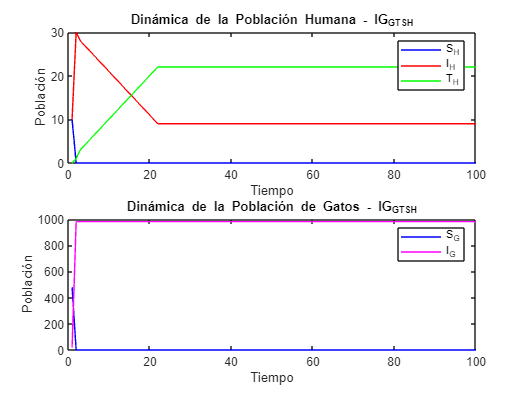

Resultados finales:
 S_H = 0.00
 I_H = 9.00
 T_H = 22.00
 I_G = 980.00
 S_G = 0.00



Analizando caso: SH_GT_IG


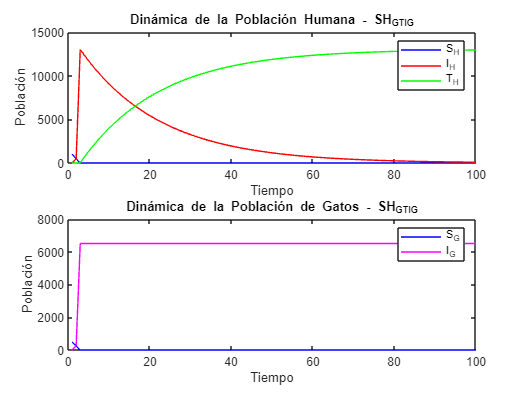

Resultados finales:
 S_H = 0.00
 I_H = 85.00
 T_H = 12944.00
 I_G = 6502.00
 S_G = 0.00



%%%Coded by Santiago Caballero Rosas,%%%

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%       |\      _,,,---,,_                 %
% ZZZzz /,`.-'`'    -.  ;-;;,_             %
%      |,4-  ) )-,_. ,\ (  `'-'            %
%     '---''(_/--'  `-'\_)  Modelo SIR-CAT % 
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

              %%%PREGUNTA IV%%%
              %CASOS ESPECIALES%

% Parámetros
beta = 0.1; % Tasa de infección
gamma_H = 0.05; % Tasa de recuperación en humanos

% Poblaciones totales
Total_H = 1000;
Total_G = 500;

% Parámetros
beta = 0.1; % Tasa de infección
gamma_H = 0.05; % Tasa de recuperación en humanos

% Poblaciones totales
Total_H = 1000;
Total_G = 500;

% Casos a analizar
cases = {'SH_0', 'SG_0', 'IG_GT_SH', 'SH_GT_IG'};

% Preasignación para gráficos
t_max = 100;
results = struct();

for c = 1:length(cases)
    fprintf('Analizando caso: %s\n', cases{c});
    
    switch cases{c}
        case 'SH_0'
            % No hay humanos susceptibles
            S_H = 0;
            I_H = 10;  % Humanos infectados iniciales
            T_H = Total_H - I_H; % Todos los demás humanos son tratados
            I_G = 5;   % Gatos infectados
            S_G = Total_G - I_G; % Todos los demás gatos son susceptibles
            
        case 'SG_0'
            % No hay gatos susceptibles
            S_H = 990; % Humanos susceptibles
            I_H = 10;  % Humanos infectados
            T_H = 0;   % Humanos tratados
            S_G = 0;   % No hay gatos susceptibles
            I_G = Total_G; % Todos los gatos están infectados
            
        case 'IG_GT_SH'
            % Más gatos infectados que humanos susceptibles
            S_H = 10;
            I_H = 10;
            T_H = 0;
            I_G = 20;
            S_G = Total_G - I_G;
            
        case 'SH_GT_IG'
            % Más humanos susceptibles que gatos infectados
            S_H = 990;
            I_H = 10;
            T_H = 0;
            I_G = 5;
            S_G = Total_G - I_G;
    end
    
    % Inicializar vectores de almacenamiento para resultados
    S_H_vals = zeros(1, t_max);
    I_H_vals = zeros(1, t_max);
    T_H_vals = zeros(1, t_max);
    S_G_vals = zeros(1, t_max);
    I_G_vals = zeros(1, t_max);
    
    % Simulación
    for t = 1:t_max
        % Almacenar resultados
        S_H_vals(t) = S_H;
        I_H_vals(t) = I_H;
        T_H_vals(t) = T_H;
        S_G_vals(t) = S_G;
        I_G_vals(t) = I_G;
        
        % Calcular las derivadas
        dS_H = round(-beta * I_G * S_H);
        dI_H = round((beta * I_G * S_H - gamma_H * I_H));
        dT_H = round(gamma_H * I_H);
        
        dS_G = round(-beta * S_G * I_G);
        dI_G = round(beta * S_G * I_G);
        
        % Actualizar poblaciones
        S_H = S_H + dS_H;
        I_H = I_H + dI_H;
        T_H = T_H + dT_H;
        
        % Verificar que las poblaciones no sean negativas
        S_H = max(S_H, 0);
        I_H = max(I_H, 0);
        T_H = max(T_H, 0);
        
        S_G = S_G + dS_G;
        I_G = I_G + dI_G;
        
        % Verificar que las poblaciones no sean negativas
        S_G = max(S_G, 0);
        I_G = max(I_G, 0);
    end
    
    % Guardar resultados en la estructura
    results.(cases{c}) = struct('S_H', S_H_vals, 'I_H', I_H_vals, 'T_H', T_H_vals, 'S_G', S_G_vals, 'I_G', I_G_vals);
    
    % Graficar los resultados
    figure;
    
    % Dinámica de la población humana
    subplot(2, 1, 1);
    plot(1:t_max, S_H_vals, 'b', 'DisplayName', 'S_H');
    hold on;
    plot(1:t_max, I_H_vals, 'r', 'DisplayName', 'I_H');
    plot(1:t_max, T_H_vals, 'g', 'DisplayName', 'T_H');
    xlabel('Tiempo');
    ylabel('Población');
    title(['Dinámica de la Población Humana - ' cases{c}]);
    legend;
    hold off;
    
    % Dinámica de la población de gatos
    subplot(2, 1, 2);
    plot(1:t_max, S_G_vals, 'b', 'DisplayName', 'S_G');
    hold on;
    plot(1:t_max, I_G_vals, 'm', 'DisplayName', 'I_G');
    xlabel('Tiempo');
    ylabel('Población');
    title(['Dinámica de la Población de Gatos - ' cases{c}]);
    legend;
    hold off;
    
    % Mostrar resultados finales para el caso actual
    fprintf('Resultados finales:\n S_H = %.2f\n I_H = %.2f\n T_H = %.2f\n I_G = %.2f\n S_G = %.2f\n\n', S_H, I_H, T_H, I_G, S_G);
end